%%Threshold image
I = imread ('Beningn1.jpg');
level = 0.1;
Ithresh = im2bw (I, level);
Ithresh8 = uint8 (Ithresh).*I;


%%Filtering image
PSF= fspecial('average',[3 3]);
NSR = 0.2;
J = deconvwnr(Ithresh8, PSF, NSR); 
K = adapthisteq(J(:,:,1),'NumTiles',[8 8],'ClipLimit',0.01);
K1=K;


%% Image Segmentation
PreProcessedImage3=[];
PreProcessedImage3(:,:,1)=K1;
PreProcessedImage3(:,:,2)=K1;
PreProcessedImage3(:,:,3)=K1;

K1=PreProcessedImage3;
Y=double(K1);
k=2; % k: number of regions
g=2; % g: number of GMM components
beta=1; % beta: unitary vs. pairwise
EM_iter=10; % max num of iterations
MAP_iter=10; % max num of iterations


[X,GMM,ShapeTexture]=image_kmeans(Y,k,g);
[X,Y,GMM]=HMRF_EM(X,Y,GMM,k,g,EM_iter,MAP_iter,beta);

Y = Y(:,:,1) =

     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2

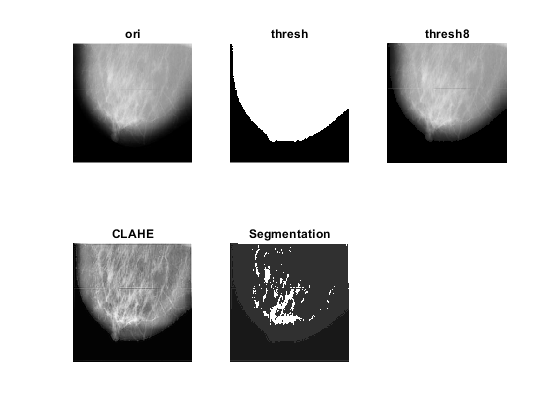


Y=Y*80;
Y=uint8(Y);
Y=rgb2gray(Y);

subplot(2,3,1), imshow(I);
title('ori');
subplot(2,3,2), imshow(Ithresh);
title('thresh');
subplot(2,3,3), imshow(Ithresh8);
title('thresh8');
subplot(2,3,4), imshow(K);
title('CLAHE');
subplot(2,3,5), imshow(Y);
title('Segmentation');